# Tracking Analysis of tubular structures

## Import videos

This section allows you to select the video files. This is only necessary for the visualization of the results. They are not used for any image analysis, since the tubule detection and tracking is performed with Mitometer. They need to be in "tiff" format, maximum 16 bit, and the name of the file should not contain points or weird simbols (/,\,*, etc).

### UI selection of the videos

%% UI selection of the mitometer tracking files
[filename,path] = uigetfile('*.*','All Files (*.*)',...
                'Select files','MultiSelect','on');
path = string(path) + string(filename); %final string with the paths
n_videos = length(filename);
clearvars -except path n_videos

## Import Data

Depending if the tracking was performed with TrackMate or with Mitometer, execute either section 1 or 2. 

### UI selection of data

We should have previously downloaded the matlab structure "trackList" obtained from Mitometer. Be careful to upload the files in the same order as for the video files. This section allows you to select all the tracking data for each video and processes it for further analysis. The files need to be in ".mat" format, and the name of the file should not contain points. 

%% UI selection of the mitometer tracking files
[filename,path2] = uigetfile('*.*','All Files (*.*)',...
                'Select files','MultiSelect','on');
path2 = string(path2) + string(filename); 
path = [path;path2];
clearvars -except path n_videos

### 1. TrackMate Data

Both the tracking data and the video file are processed and saved into the variable called "video_file". They are then saved in the folder "temp" of the local directory, to reduce RAM useage. They will be loaded from this folder everytime that they are needed. 

for i = 1:n_videos
    [video_file] = LoadTrackmateData(i,path);
    %Save original loaded files in disk
    dir = what('temp');
    filename = string(dir.path) + "\" + "video_" + i + ".mat";
    save(filename,'video_file','-v7.3')
end
clearvars -except path n_videos

### 2. Mitometer Data

Both the tracking data and the video file are processed and saved into the variable called "video_file". They are then saved in the folder "temp" of the local directory, to reduce RAM useage. They will be loaded from this folder everytime that they are needed. 

for i = 1:n_videos
    [video_file] = LoadMitoData(i,path);
    %Save original loaded files in disk
    dir = what('temp');
    filename = string(dir.path) + "\" + "video_" + i + ".mat";
    save(filename,'video_file','-v7.3')
end
clearvars -except path n_videos

## Visualization of the tracks

This can only be used for Mitometer data. TrackMate data does not contain information about the shape. Here we can visualize the tracks for each frame. It shows only the tracks occuring in that frame, and the frames from the beggining up to that frame. Select the video number (i), and the frame (f). 

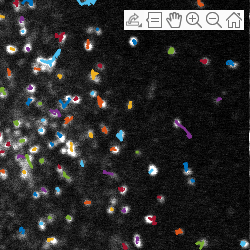

i = 1; %select the video number
f = 10; %select the frame number
%% Loading of the data from disk (video_file)
dir = what('temp');
filename = string(dir.path) + "\" + "video_" + i + ".mat";
load(filename);
%% Image representation with tracks in that frame
list = find(~isnan(video_file{1,4}(:,f)));
imshow(video_file{1,3}(:,:,f))
hold on
for j = 1:length(list)
    t = list(j,1);
    x = video_file{1,4}(t,1:f);
    x = x(~isnan(x));
    y = video_file{1,5}(t,1:f);
    y = y(~isnan(y));
    plot(x,y,'LineWidth',2)
end

clearvars -except path n_videos th

Execute this section if you want to save a video file as ".avi" showing the trajectories in time. 

i = 8; %select the video number
%% Loading of the data from disk (video_file)
dir = what('temp');
filename = string(dir.path) + "\" + "video_" + i + ".mat";
load(filename);
%% Image representation with tracks in that frame
for f = 1:width(video_file{1,4})
    imshow(video_file{1,3}(:,:,f))
    hold on
    list = find(~isnan(video_file{1,4}(:,f)));
    for j = 1:length(list)
        t = list(j,1);
        if f<=3
            x = video_file{1,4}(t,1:f);
            y = video_file{1,5}(t,1:f);
        else
            x = video_file{1,4}(t,f-3:f);
            y = video_file{1,5}(t,f-3:f);
        end
        x = x(~isnan(x));
        y = y(~isnan(y));
        plot(x,y,'LineWidth',0.5,'Color','r')
    end
    F(f) = getframe(gcf);
    hold off
end

writerObj = VideoWriter('myVideo','Uncompressed AVI');
writerObj.FrameRate = 1;
open(writerObj);
for f = 1:length(F)
    % convert the image to a frame
    frame = F(f);
    writeVideo(writerObj, frame);
end
close(writerObj)
clearvars -except path n_videos th

## Decision of the aspect ratio

The classification by aspect ratio can only be used for data obtained from Mitometer. Trackmate data does not contain this information. 

In this section, one can visualize different videos and frames together with the detected structures. It will only show coordinates of the structures with the selected aspect ratio. The higher the aspect ratio, the more elongated the structure is. 

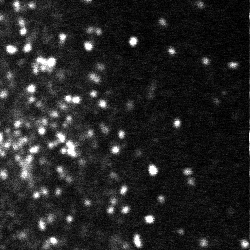

i = 1; %select the video number
f = 10; %select the frame number
th = 1.8; %select the threshold for the aspect ratio
%% Loading of the data from disk (video_file)
dir = what('temp');
filename = string(dir.path) + "\" + "video_" + i + ".mat";
load(filename);
%% Image representation with coordinates
imshow(video_file{1,3}(:,:,f))
hold on

logi = video_file{1,8}(:,f) < th;

Index in position 2 exceeds array bounds. Index must not exceed 5.

x = video_file{1,4}(logi,f);
y = video_file{1,5}(logi,f);
scatter(x,y,'+','r')
hold off
clearvars -except path n_videos th

## Calculation of the velocity histogram

This section calculates the instananeos velocity, i.e. the desplacement from one frame to the next divided by the time. Therefore, it is necessary to indicate the frame rate and the pixel size. 

dt = 2; %frame rate in seconds
pixel_size = 0.06; %in nm/px

pixel_size = 0.0600

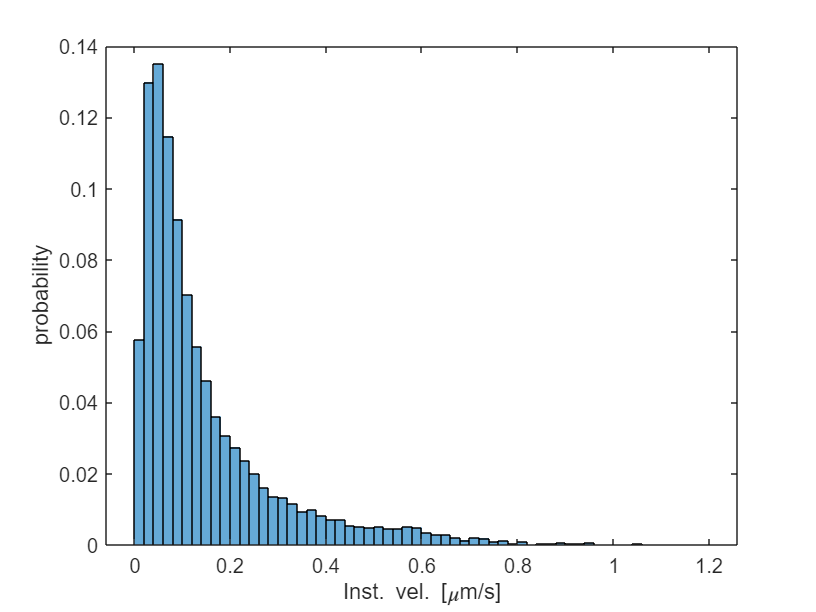

v_total = [];
for i = 1:n_videos
    %Load from disk
    dir = what('temp');
    filename = string(dir.path) + "\" + "video_" + i + ".mat";
    load(filename);
    [velocity_i] = InstantVelocity(video_file,pixel_size,dt);
    velocity_i = reshape(velocity_i(~isnan(velocity_i)),[],1);
    v_total = [v_total;velocity_i];
end
figure
[~,edges] = histcounts(v_total);
histogram(v_total,edges,'Normalization','probability')
xlabel('Inst. vel. [\mum/s]')
ylabel('probability')
hold off

clearvars -except path n_videos th 

If you want to plot the rounded structures vs the elongated ones, execute this section. All structures are classified in elongated or rounded whether they are considered like this most of the time (more than 50% of the trajectory). 

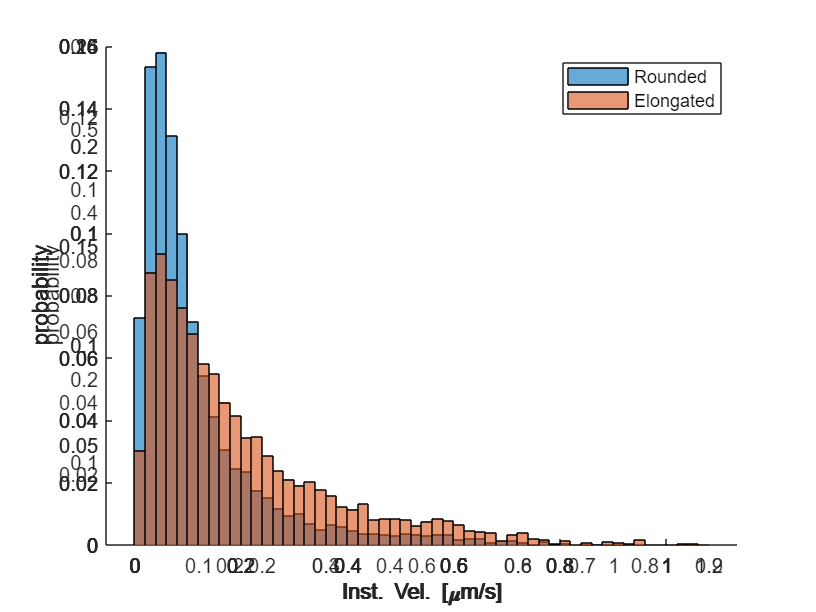

dt = 2; %frame rate in seconds
pixel_size = 0.06; %in nm/px
v_long = [];
v_round = [];
for i = 1:n_videos
    %Load from disk
    dir = what('temp');
    filename = string(dir.path) + "\" + "video_" + i + ".mat";
    load(filename);
    %Calculatio of velocity
    [velocity_i] = InstantVelocity(video_file,pixel_size,dt);
    %Filtering by rounded
    logi = video_file{1,8}(:,:) < th; %logical for rounded structures (> for rounded)
    round_num = sum(double(logi),2,"omitnan");%number of rounded structures per traj
    str = sum(double(~isnan(video_file{1,8})),2,"omitnan"); %number of structures per traj
    ratio = round_num./str;
    label = ratio > 0.5;
    v_filtered = velocity_i(label,:);
    v_filtered = reshape(v_filtered(~isnan(v_filtered)),[],1);
    v_round = [v_round;v_filtered];
    %Filtering by elongated
    v_filtered = velocity_i(~label,:);
    v_filtered = reshape(v_filtered(~isnan(v_filtered)),[],1);
    v_long = [v_long;v_filtered];
end
% Plotting all results
h = axes;
h.XLabel.String = 'Inst. Vel. [\mum/s]';
h.YLabel.String = 'probability';
hold(h,'on')
[~,edges] = histcounts(v_round);
histogram(v_round,edges,'Normalization','probability','Parent',h);
h.Children(1,1).DisplayName = 'Rounded';
histogram(v_long,edges,'Normalization','probability','Parent',h);
h.Children(1,1).DisplayName = 'Elongated';
hold(h,'off')
legend

clearvars -except path n_videos th 

## Calculation of the Diffusion Coefficient

This section calculates the instantaneous diffussion coefficient, which corresponds to the linear fit of msd values for the first 4 t lags. Therefore, it is necessary to indicate the frame rate and the pixel size.

dt = 2; %frame rate in seconds
pixel_size = 0.06; %in nm/px

pixel_size = 0.0600

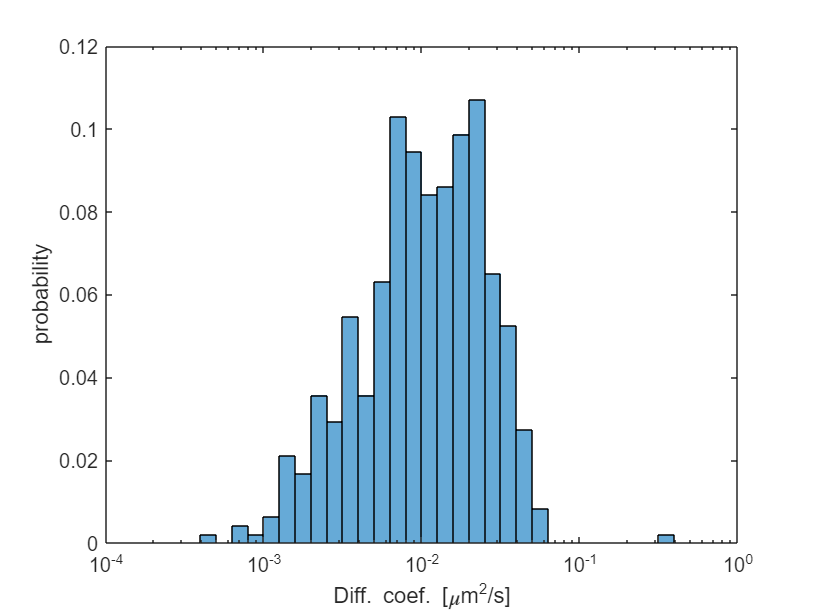

Dif_allvideos = [];
for i = 1:n_videos
    %Load from disk
    dir = what('temp');
    filename = string(dir.path) + "\" + "video_" + i + ".mat";
    load(filename);
    [Dif_i] = MSD(video_file,pixel_size,dt);
    Dif_i = Dif_i(~isnan(Dif_i),1);
    Dif_allvideos = [Dif_allvideos;Dif_i];
end
figure
[~,edges] = histcounts(log10(Dif_allvideos));
histogram(Dif_allvideos,10.^(edges(1,1):0.1:edges(1,end)),'Normalization','probability')
set(gca, 'xscale','log')
xlabel('Diff. coef. [\mum^2/s]')
ylabel('probability')
hold off

clearvars -except path n_videos th 

 If you want to plot the rounded structures vs the elongated ones, execute this section. All structures are classified in elongated or rounded whether they are considered like this most of the time (more than 50% of the trajectory). 

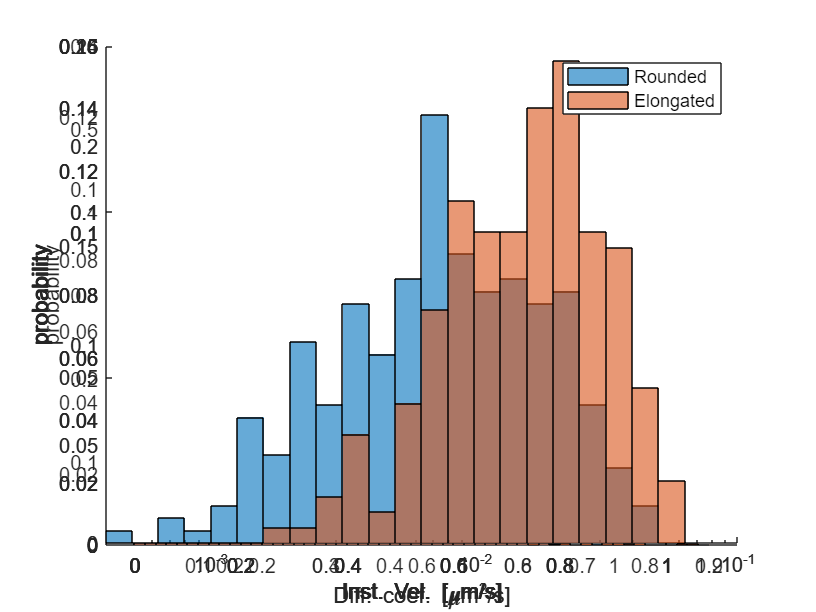

dt = 2; %frame rate in seconds
pixel_size = 0.06; %in nm/px
Dif_long = [];
Dif_round = [];
for i = 1:n_videos
    %Load from disk
    dir = what('temp');
    filename = string(dir.path) + "\" + "video_" + i + ".mat";
    load(filename);
    [Dif_i] = MSD(video_file,pixel_size,dt);
    %Filtering by rounded
    logi = video_file{1,8}(:,:) < th;
    round_num = sum(double(logi),2,"omitnan");%number of rounded structures per traj
    str = sum(double(~isnan(video_file{1,8})),2,"omitnan"); %number of structures per traj
    ratio = round_num./str;
    label = ratio > 0.5;
    d_filtered = Dif_i(label);
    d_filtered = d_filtered(~isnan(d_filtered),1);
    Dif_round = [Dif_round;d_filtered];
    %Filtering by elongated
    d_filtered = Dif_i(~label);
    d_filtered = d_filtered(~isnan(d_filtered),1);
    Dif_long = [Dif_long;d_filtered];
end
% Plotting all results
a = axes;
a.XScale = 'log';
a.XLabel.String = 'Diff. coef. [\mum^2/s]';
a.YLabel.String = 'probability';
hold(a,'on')
[~,edges] = histcounts(log10(Dif_round));
histogram(Dif_round,10.^(edges(1,1):0.1:edges(1,end)),'Normalization','probability','Parent',a);
a.Children(1,1).DisplayName = 'Rounded';
histogram(Dif_long,10.^(edges(1,1):0.1:edges(1,end)),'Normalization','probability','Parent',a);
a.Children(1,1).DisplayName = 'Elongated';
hold(a,'off')
legend

clearvars -except path n_videos th 